# Exercise 1

a) Sample from gaussian process.

The code for getting the relevant samples is at the end of the matlab livescript, due to how matlab processes functions I have to order stuff like this.

b) Use a set of kernels, draw 5 realizations from them, and then plot them.

There is no strict instructions on the number of features to use, but because we have to plot them I feel that anything more than 2d is hard to visualize. So I will assume that 2 feature vectors is good enough.

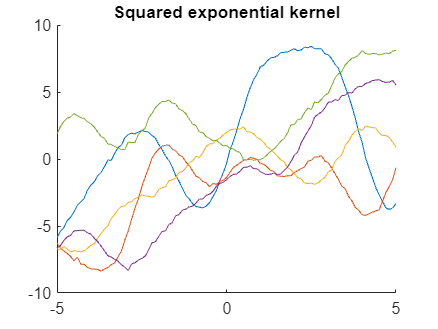

% For the square exponential kernel, I need two parameters, the l and the
% variance. For the lengthscale I'll assume 1 is good enough, for the
% variance I'll just the variance formula of the uniform

x_range = [-5 5];
variance = ((x_range(2)-x_range(1)).^2)/12;

% I assumed that the lengthscale is just a 1
% 1 squared is 1, so the denominator is just a division by 2
squared_exp_kernel = @(x, y) variance*exp(-((x-y)^2)/2);
mean_funct = @(x) mean(x, 1);
features = 1;
x_vals = -5:0.1: 5;

clf
hold on
title('Squared exponential kernel')
for i=1:5
    squared_samples = gaussian_process_nice(mean_funct, squared_exp_kernel, x_vals);
    plot(x_vals, squared_samples)
end
hold off

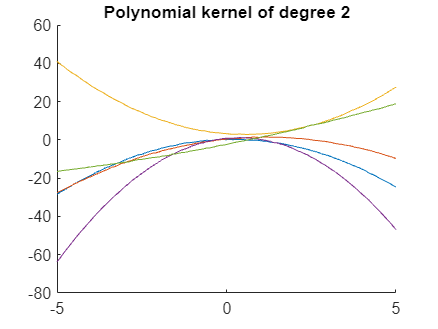

% For the polynomial kernel of degree 2, I'll assume the alpha=1 is good enough
poly_2_kernel = @(x,y) (x.'*y + 1)^2;

clf
hold on
title('Polynomial kernel of degree 2')
for i=1:5
    poly_samples = gaussian_process_nice(mean_funct, poly_2_kernel, x_vals);
    plot(x_vals, poly_samples)
end
hold off

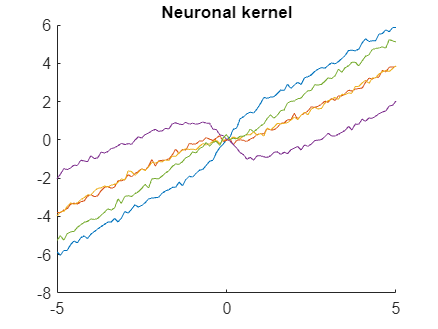

% For the neuronal kernel, I need a helper function a
a_func = @(x, y) 2*y.'*sum(x);
neuronal_kern = @(x, y) (2/pi)*asin(a_func(x,y)/(sqrt((1+a_func(x,x))*(1+a_func(y,y)))));

clf
hold on
title('Neuronal kernel')
for i=1:5
    neur_samples = gaussian_process_nice(mean_funct, neuronal_kern, x_vals);
    plot(x_vals, neur_samples)
end
hold off

# Exercise 2

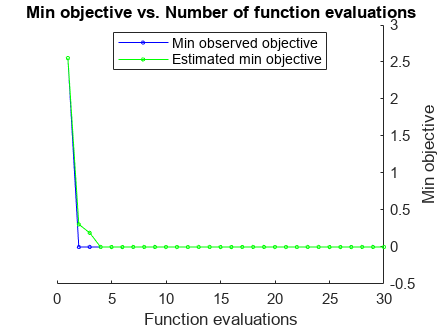

data_x = [-1; -2; 1; 2];
data_y = [1; 4; 1; 4];

% So... there's a way of optimizing the hyper parameters!
% I'm optimizing all of the available values, except for the kernel
% function. Because that was defined in advance
% It already does bayesian optimization, so that is finished.
% Here is the documentation: https://nl.mathworks.com/help/stats/fitrgp.html#butnn96_sep_shared-HyperparameterOptimizationOptions
gprModel = fitrgp(data_x, data_y, 'KernelFunction','squaredexponential', ...
    'OptimizeHyperparameters', {'BasisFunction','KernelScale','Sigma','Standardize'}, ...
    'HyperparameterOptimizationOptions',struct('Verbose',0));


% First I'll display the predicted value at 0
pred_at_0 = predict(gprModel, 0)

pred_at_0 = -6.6570e-16

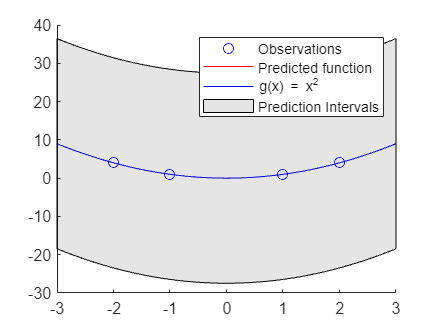

x = linspace(-3,3)';
[ypred,~,yint] = predict(gprModel, x);

clf
hold on
% Plotting the observations as well
scatter(data_x,data_y,'b')
plot(x,ypred,'r')
% Plotting reality for comparison, because we know it's x^2
fplot(@(x) x.^2,[-3, 3],'b')
patch([x;flipud(x)],[yint(:,1);flipud(yint(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
legend('Observations', 'Predicted function','g(x) = x^2', 'Prediction Intervals')
hold off

So... all of the plots end up overlaying pretty much over each other perfectly. I'll just plot the predicted function and the interval separately again. Even though it's just a straight line... again

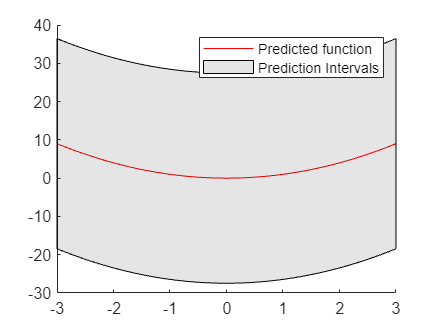

clf
hold on
% Plotting the observations as well
plot(x,ypred,'r')
% Plotting reality for comparison, because we know it's x^2
patch([x;flipud(x)],[yint(:,1);flipud(yint(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
legend('Predicted function', 'Prediction Intervals')
hold off

function samples = gaussian_process_nice(mean_funct, kernel_func, x_vals)
    % Method to get multiple samples with a given mean and kernel function
    % x_range is drawn according to a uniform distribution, should contain
    % the minimum and the maximum

    % Assumes X is a vector input

    % Mvnrnd does pretty much most of what I need
    % I just need to generate the relevant values that will be passed to
    % the kernel and mean functions, then pass them to mvnrnd and donezo

    mu = mean_funct(x_vals)';

    % For the kernel_funct... I'll just do 2 for loops for each pairwise
    % element
    sigma = zeros(length(x_vals));

    for i=1:length(x_vals)
        for j=1:length(x_vals)
            sigma(i, j) = kernel_func(x_vals(i), x_vals(j));
        end
    end

    % It's not technically part of the process, but as recommended in b
    % I'll increase sigma (K) with a slight value of the identity matrix,
    % to make things flow better
    sigma = sigma + 0.01*eye(length(x_vals));

    samples = mvnrnd(mu, sigma);
end
